# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

**Train**

% List training files
normalFiles = dir("Train/Normal/*.wav");
faultyFiles = dir("Train/Faulty/*.wav");

numNormalSamples = length(normalFiles);
numFaultySamples = length(faultyFiles);

% Prepare input and label matrices
xFiles = [normalFiles; faultyFiles];
y = [repmat({'N'}, numNormalSamples, 1)
     repmat({'F'}, numFaultySamples, 1)];

% Shuffle X and y
numSamples = length(y);
idx = randperm(numSamples);
xFiles = xFiles(idx, :);
y = y(idx);

numFeatures = 1e6;
X = zeros(numSamples, numFeatures); % preallocate feature matrix
for i = 1:numSamples
    switch y{i}
        case 'N'
            [x, Fs] = audioread("Train/Normal/" + xFiles(i).name);
        case 'F'
            [x, Fs] = audioread("Train/Faulty/" + xFiles(i).name);
    end

    % Perform feature extraction
    rmsFunc = dsp.MovingRMS(480);
    movingRMS = rmsFunc(x);
    reshapedMovingRMS = reshape(movingRMS, 1, []);

    FFT = fft(x);
    reshapedFFT = reshape(abs(FFT), 1, []);

    windowLength = 4800;
    window = hamming(windowLength);
    overlap = floor(windowLength/2);
    spec = spectrogram(x, window, overlap);
    reshapedSpec = reshape(abs(spec), 1, []);

    window = hann(windowLength, "periodic");
    coeffs = mfcc(x, Fs, 'Window', window, 'OverlapLength', overlap);
    reshapedCoeffs = reshape(coeffs, 1, []);

    [cA, cD] = dwt(x, 'db2');
    [cA1, cD1] = dwt(cA, 'db2');
    [cA2, cD2] = dwt(cA1, 'db2');
    [cA3, cD3] = dwt(cA2, 'db2');
    [cA4, cD4] = dwt(cA3, 'db2');
    [cA5, cD5] = dwt(cA4, 'db2');
    [cA6, cD6] = dwt(cA5, 'db2');
    [cA7, cD7] = dwt(cA6, 'db2');
    [cA8, cD8] = dwt(cA7, 'db2');
    [cA9, cD9] = dwt(cA8, 'db2');
    combinedDwt = [cA9', cD9'];

    % Pack the extracted feature vector to a new row of the feature matrix X
    combinedFeatures = [normalize(reshapedMovingRMS), normalize(reshapedFFT), normalize(reshapedSpec), normalize(reshapedCoeffs), normalize(combinedDwt)];
    if length(combinedFeatures) > numFeatures
        combinedFeatures = combinedFeatures(1:numFeatures);
    end
    
    % If the combined features are shorter than the desired number, pad with zeros
    if length(combinedFeatures) < numFeatures
        combinedFeatures = [combinedFeatures, zeros(1, numFeatures - length(combinedFeatures))];
    end
    X(i, :) = combinedFeatures;
end

% Training set splitting and model training
hpartition = cvpartition(y, 'Holdout', 0.2);

idxTrain = training(hpartition);
idxTest = test(hpartition);

XTrain = X(idxTrain, :);
yTrain = y(idxTrain);

XTest = X(idxTest, :);
yTest = y(idxTest);
% model = fitctree(XTrain, yTrain);
model = fitcecoc(XTrain, yTrain);
% model = fitcnb(XTrain, yTrain);

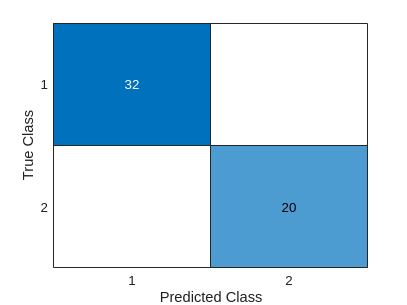

% Predict the labels for the test set
labels = predict(model, XTest);

% Confusion matrix
[m, cats] = confusionmat(yTest, labels);

% Number of correct predictions (diagonal of the confusion matrix)
numCorrect = sum(diag(m));

% Accuracy calculation
accuracy = numCorrect / numel(yTest);

% Precision, recall, and F1-score
tp = diag(m); % True positives
precision = tp ./ sum(m, 2); % Precision for each class
recall = tp ./ sum(m, 1)'; % Recall for each class
f1 = 2 .* precision .* recall ./ (precision + recall); % F1-score for each class

% Mean F1-score across all classes
f1Mean = mean(f1);

% Display confusion matrix
confusionchart(m);


% Output results
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 1


disp(['F1-Score Mean: ', num2str(f1Mean)]);

F1-Score Mean: 1


disp(['Precision: ', num2str(precision')]); % Display precision for each class

Precision: 1  1


disp(['Recall: ', num2str(recall')]); % Display recall for each class

Recall: 1  1


% Prepare unknown files
unknownFiles = dir("Train/Faulty/*.wav");
unknownFilenames = struct2table(unknownFiles);
unknownFilenames = sortrows(unknownFilenames, 'name');
unknownFiles = table2struct(unknownFilenames);
predictedLabelsStr = "";

for i = 1:length(unknownFiles)
    [x, Fs] = audioread("Train/Faulty/" + unknownFiles(i).name);
    
    % Perform prediction and printing results
    rmsFunc = dsp.MovingRMS(480);
    movingRMS = rmsFunc(x);
    reshapedMovingRMS = reshape(movingRMS, 1, []);

    FFT = fft(x);
    reshapedFFT = reshape(abs(FFT), 1, []);

    windowLength = 4800;
    window = hamming(windowLength);
    overlap = floor(windowLength/2);
    spec = spectrogram(x, window, overlap);
    reshapedSpec = reshape(abs(spec), 1, []);

    window = hann(windowLength, "periodic");
    coeffs = mfcc(x, Fs, 'Window', window, 'OverlapLength', overlap);
    reshapedCoeffs = reshape(coeffs, 1, []);

    [cA, cD] = dwt(x, 'db2');
    [cA1, cD1] = dwt(cA, 'db2');
    [cA2, cD2] = dwt(cA1, 'db2');
    [cA3, cD3] = dwt(cA2, 'db2');
    [cA4, cD4] = dwt(cA3, 'db2');
    [cA5, cD5] = dwt(cA4, 'db2');
    [cA6, cD6] = dwt(cA5, 'db2');
    [cA7, cD7] = dwt(cA6, 'db2');
    [cA8, cD8] = dwt(cA7, 'db2');
    [cA9, cD9] = dwt(cA8, 'db2');
    combinedDwt = [cA9', cD9'];

    combinedFeatures = [normalize(reshapedMovingRMS), normalize(reshapedFFT), normalize(reshapedSpec), normalize(reshapedCoeffs), normalize(combinedDwt)];
    combinedFeatures = [combinedFeatures, zeros(1, 1000000 - numel(combinedFeatures))];
    predictedLabel = predict(model, combinedFeatures);
    % fprintf("File: %s, Predicted Label: %s\n", unknownFiles(i).name, char(predictedLabel));
    fprintf("%s ", char(predictedLabel));
end

F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F F 

save('model.mat', "model")

normalFiles = dir("Train/Normal/*.wav");
faultyFiles = dir("Train/Faulty/*.wav");

numNormalSamples = length(normalFiles);
numFaultySamples = length(faultyFiles);

% Prepare input and label matrices
xFiles = [normalFiles; faultyFiles];
y = [repmat({'N'}, numNormalSamples, 1)
     repmat({'F'}, numFaultySamples, 1)];

y = categorical(y);

numSamples = length(y);
idx = randperm(numSamples);
newData = xFiles(idx, :);
newLabels = y(idx);

% Split training data into a training set and a test set
partition = cvpartition(newLabels, 'Holdout', 0.2);

idxTrain = training(partition);
idxTest = test(partition);

XTrain = newData(idxTrain);
yTrain = newLabels(idxTrain);

XTest = newData(idxTest);
yTest = newLabels(idxTest);

% Split the test set further into a validation set and a smaller test set
partition = cvpartition(yTest, 'Holdout', 0.5);

idxVal = training(partition);
idxTest = training(partition);

XVal = XTest(idxVal);
yVal = yTest(idxVal);

XTest = XTest(idxTest);
yTest = yTest(idxTest);

FTrain = cell(length(XTrain), 1);
FVal = cell(length(XVal), 1);
FTest = cell(length(XTest), 1);
fftLength = 256;  % Adjust this as needed

for i = 1:length(XTrain)
    [yData, fs] = audioread(fullfile(XTrain(i).folder, XTrain(i).name));
    fftData = abs(fft(yData, fftLength));
    FTrain{i} = fftData';  % Transpose to get size (1, fftLength)
end

for i = 1:length(XVal)
    [yData, fs] = audioread(fullfile(XVal(i).folder, XVal(i).name));
    fftData = abs(fft(yData, fftLength));
    FVal{i} = fftData';
end

for i = 1:length(XTest)
    [yData, fs] = audioread(fullfile(XTest(i).folder, XTest(i).name));
    fftData = abs(fft(yData, fftLength));
    FTest{i} = fftData';
end


numHiddenUnits = 120;
classNames = categories(yTrain);
numClasses = numel(classNames);  % Update numClasses based on actual data

featureSize = fftLength;  % Set featureSize to match the reshaped FFT length


% Update the input layer to match the feature size
layers = [
    sequenceInputLayer(featureSize)  % Set to feature size
    lstmLayer(numHiddenUnits, OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer];

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    InitialLearnRate=0.005,...
    GradientThreshold=1, ...
    Shuffle="never", ...
    ValidationData={FVal, yVal}, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

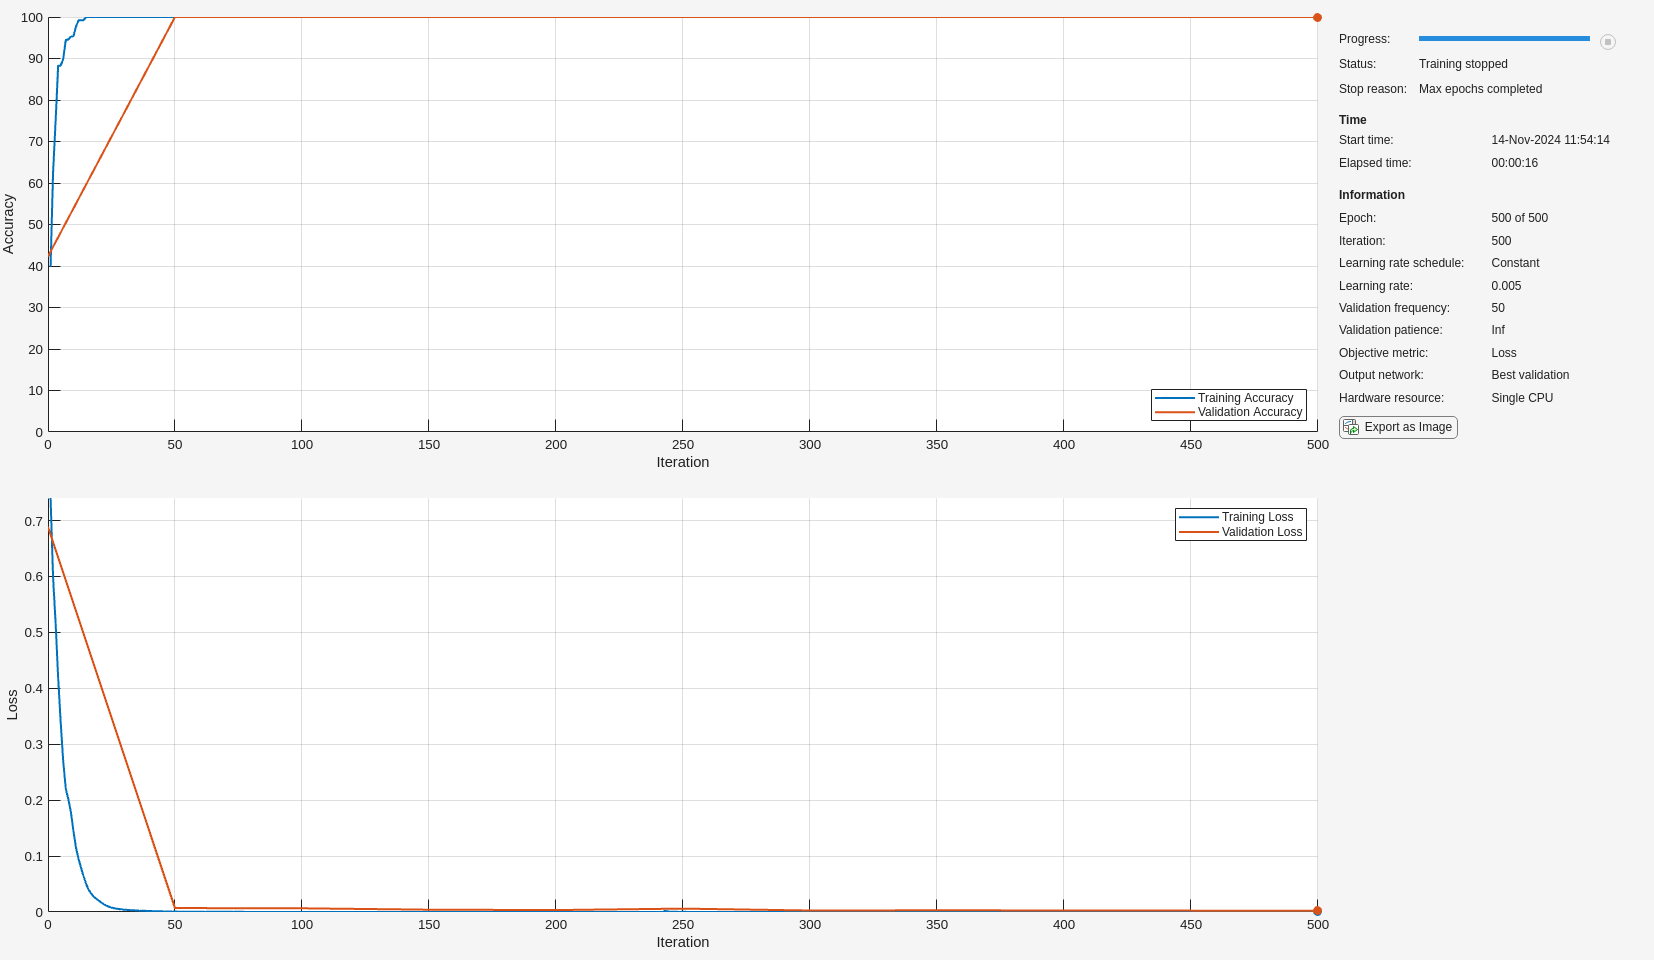

net = trainnet(FTrain, yTrain, layers, "crossentropy", options);

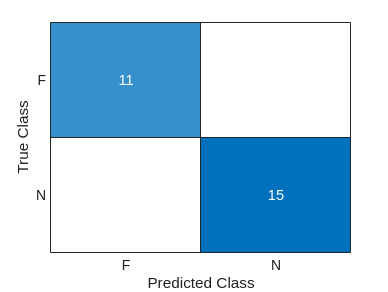

scores = minibatchpredict(net, FTest, SequencePaddingDirection="left");
yPred = scores2label(scores, classNames);
figure
confusionchart(yTest, yPred)

% Compute accuracy
[m, cats] = confusionmat(yTest, yPred);
numCorrect = sum(diag(m));
accuracy = numCorrect / numel(XTest)

accuracy = 1


% Precision, recall, and F1-score
tp = diag(m);
precision = tp ./ sum(m, 2)

precision =      1
     1


recall = tp ./ sum(m, 1)'

recall =      1
     1


f1 = 2 .* precision .* recall ./ (precision + recall)

f1 =      1
     1


f1Mean = mean(f1)

f1Mean = 1

save('net.mat', "net")
save("classNames.mat", "classNames")